%% Initialisierung
clear; % Löscht Variablen im Workspace
clc; % Löscht die Befehlszeile

% ---- Tiefpass-Teil ----
% Gegebene Werte für Tiefpass
R1_Tiefpass = 6.8e3; % Ohm
R2_Tiefpass = 68e3; % Ohm
R3_Tiefpass = 33e3; % Ohm
C1_Tiefpass = 330e-12; % Farad
C2_Tiefpass = 150e-12; % Farad
C3_Tiefpass = 22e-12; % Farad
zeta_Tiefpass = 0.607; % Angenommener Wert für das Dämpfungsverhältnis

% Symbolische Variable s definieren
s = tf('s');

% Cut-off Frequenzen für Tiefpass berechnen
fc1_Tiefpass = 1 / (2 * pi * R1_Tiefpass * C1_Tiefpass);
fc2_Tiefpass = 1 / (2 * pi * sqrt(R2_Tiefpass * R3_Tiefpass * C2_Tiefpass * C3_Tiefpass));

disp(['fc1_Tiefpass: ', num2str(fc1_Tiefpass), ' Hz']);

fc1_Tiefpass: 70924.6627 Hz


disp(['fc2_Tiefpass: ', num2str(fc2_Tiefpass), ' Hz']);

fc2_Tiefpass: 58485.9752 Hz



% Tiefpass-Übertragungsfunktionen definieren
% RC Tiefpass
T_RC_Tiefpass = 1 / (1 + s / (2 * pi * fc1_Tiefpass));
% Sallen-Key Tiefpass
T_SK_Tiefpass = (2 * pi * fc2_Tiefpass)^2 / (s^2 + s * 2 * pi * fc2_Tiefpass * 2 * zeta_Tiefpass + (2 * pi * fc2_Tiefpass)^2);

% Gesamtübertragungsfunktion für Tiefpass berechnen
Gesamt_Tiefpass = T_RC_Tiefpass * T_SK_Tiefpass;

Gesamtübertragungsfunktion Tiefpass:


  tf with properties:

       Numerator: {[0 0 0 6.0178e+16]}
     Denominator: {[1 8.9175e+05 3.3385e+11 6.0178e+16]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% ---- Hochpass-Teil ----
% Gegebene Werte für Hochpass
R1_Hochpass = 4.3e3; % Ohm
R2_Hochpass = 22e3; % Ohm
R3_Hochpass = 100e3; % Ohm
C1_Hochpass = 680e-12; % Farad
C2_Hochpass = 68e-12; % Farad
C3_Hochpass = 68e-12; % Farad
zeta_Hochpass = 0.707; % Angenommener Wert für das Dämpfungsverhältnis

% Cut-off Frequenzen für Hochpass berechnen
fc1_Hochpass = 1 / (2 * pi * R1_Hochpass * C1_Hochpass);
fc2_Hochpass = 1 / (2 * pi * sqrt(R2_Hochpass * R3_Hochpass * C2_Hochpass * C3_Hochpass));

disp(['fc1_Hochpass: ', num2str(fc1_Hochpass), ' Hz']);

fc1_Hochpass: 54430.5551 Hz


disp(['fc2_Hochpass: ', num2str(fc2_Hochpass), ' Hz']);

fc2_Hochpass: 49899.9234 Hz



% Hochpass-Übertragungsfunktionen definieren
% RC Hochpass
H_RC_Hochpass = s / (s + 2 * pi * fc1_Hochpass);
% Sallen-Key Hochpass
H_SK_Hochpass = s^2 / (s^2 + s * 2 * pi * fc2_Hochpass * 2 * zeta_Hochpass + (2 * pi * fc2_Hochpass)^2);

% Gesamtübertragungsfunktion für Hochpass berechnen
Gesamt_Hochpass = H_RC_Hochpass * H_SK_Hochpass;

% ---- Bandpass-Teil ----
% Berechnung der Gesamtübertragungsfunktion für den Bandpass
Gesamt_Bandpass = Gesamt_Tiefpass * Gesamt_Hochpass;

% Übertragungsfunktionen anzeigen
disp('Gesamtübertragungsfunktion Bandpass:');

Gesamtübertragungsfunktion Bandpass:


disp(Gesamt_Bandpass);

  tf with properties:

       Numerator: {[0 0 0 6.0178e+16 0 0 0]}
     Denominator: {[1 1.6771e+06 1.2841e+12 5.7884e+17 1.6067e+23 2.6263e+28 2.0231e+33]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



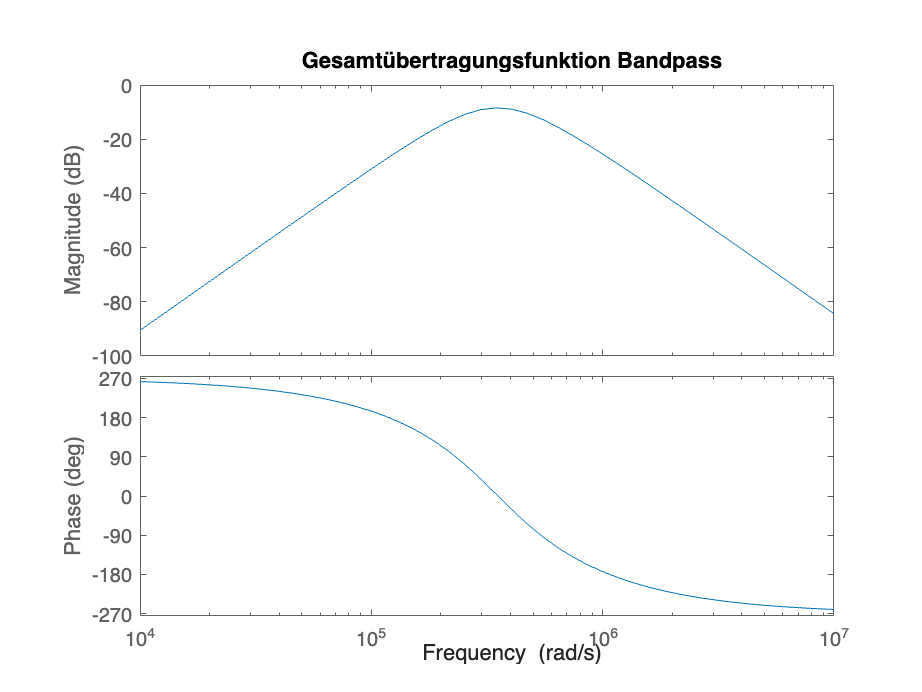


% Bode-Diagramm für Bandpass zeichnen
figure;
bode(Gesamt_Bandpass);
title('Gesamtübertragungsfunktion Bandpass');